JellyfishVideo = VideoReader("Jellyfish.mp4")

JellyfishVideo =   VideoReader with properties:

   General Properties:
            Name: 'Jellyfish.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Jellyfish'
        Duration: 7.1071
     CurrentTime: 0
       NumFrames: 213

   Video Properties:
           Width: 360
          Height: 640
       FrameRate: 29.9700
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


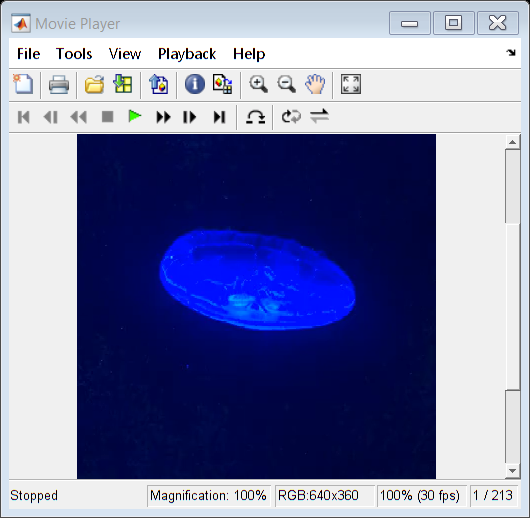

implay("Jellyfish.mp4")

frame_1 = read(JellyfishVideo,1);
frame_30 = read(JellyfishVideo,30);
frame_122 = read(JellyfishVideo,122);
frame_200 = read(JellyfishVideo,200);

[BW,maskedRGB] = createMaskJellyfish(frame_200);

numFrames_Jellyfish= JellyfishVideo.NumFrames;
v_seg= VideoWriter("Boxed_Jellyfish","MPEG-4");

v_seg.FrameRate = JellyfishVideo.FrameRate;
v_seg_comb.FrameRate = JellyfishVideo.FrameRate;
%open(v_seg);
bboxes = [];
idxes  = [];
for i = 1 : numFrames_Jellyfish
    frame = read(JellyfishVideo,i);
    idx = string(i);
    while strlength(idx) ~= 3
        idx = append("0",idx);
    end
    %imwrite(frame,"Jellyfish-"+idx+".png");
    [Th,maskedRGBImage] = createMaskJellyfish(frame);
    [BW,maskedImage] = segmentImageJellyfish(maskedRGBImage);
    %imwrite(frame,"MaskedJellyfish-"+idx+".bmp");
    BW = filterRegionsJellyfish(BW);
    props = regionprops("table",BW,"BoundingBox");
    BoxedJellyfish =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg, BoxedJellyfish);
    bboxes = [bboxes;props];
    idxes = [idxes;i];
    
end
%close(v_seg);

bboxes

bboxes = 213×1 table
              BoundingBox          
    _______________________________

    84.5    243.5      194       99
    83.5    243.5      196      100
    83.5    243.5      197      101
    83.5    243.5      197      102
    81.5    243.5      200      103
    81.5    243.5      200      105
    81.5    242.5      201      107
    81.5    241.5      202      108
    81.5    240.5      203      111
    82.5    238.5      202      115
    83.5    237.5      202      117
    85.5    236.5      201      119
    85.5    233.5      201      123
    85.5    231.5      202      128
    87.5    229.5      201      128
    87.5    227.5      201      131


coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

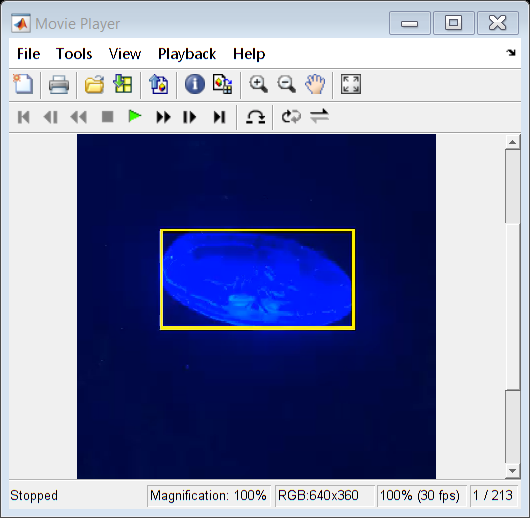

implay("Boxed_Jellyfish.mp4")

binary_vid = VideoReader("Boxed_Jellyfish.mp4");
frame_1 =  logical(im2gray(read(binary_vid,203)));
frame_38 = logical(im2gray(read(binary_vid,38)));
frame_50 = logical(im2gray(read(binary_vid,50)));